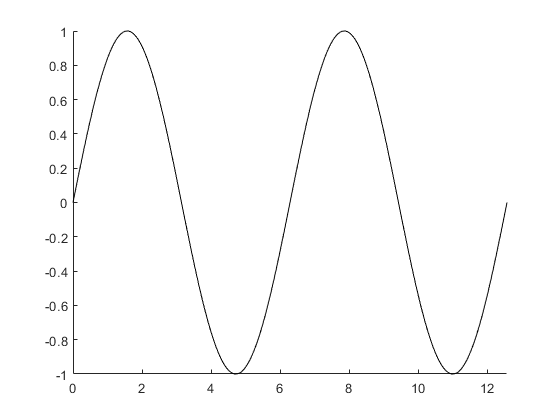

h = animatedline;
axis([0,4*pi,-1,1])

numpoints = 100000;
x = linspace(0,4*pi,numpoints);
y = sin(x);
i = 1;
for k = 1:100:numpoints-99
    xvec = x(k:k+99);
    yvec = y(k:k+99);
    addpoints(h,xvec,yvec)
    drawnow
    M(i) = getframe;
    i = i+1;
end

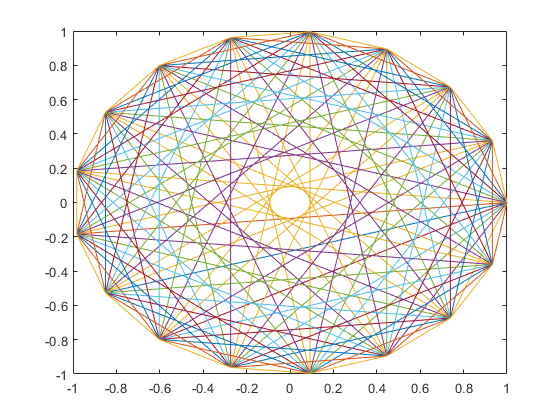

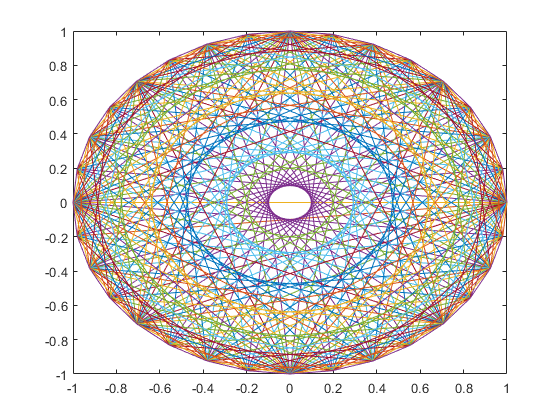

figure;
for k = 1:16
	plot(fft(eye(k+16)))
	axis([-1 1 -1 1])
	M(k) = getframe;
end


## load data

    lt_org = [255, 166 , 38]/255;
    dk_org = [255, 120, 0]/255;
    lt_blue = [50, 175, 242]/255;
    dk_blue = [0, 13, 242]/255;
    h = figure;
    set(h,'Position',[200,0,350*2,500*2]);
    ax = gca;
    ax.XLim = [-0.4 0.4];
    ax.YLim = [-12050 50];
    axis off;
    line([0 0],[-12050 0],'Color',[0.7 0.7 0.7],'LineWidth',1); hold on;
    last_i = 1;
    j=1;
    for i = 1:50:12048
        temp = pkData(pkData(:,1)<i & pkData(:,1)> last_i ,:);
        lineh = line([-.4 0.4],[-i -i],'LineWidth',2,'Color','k');
        if ~isempty(temp)
            numEvents = size(temp,1);
            
            line([-temp(:,2)'; zeros(1,numEvents)],[-temp(:,1)'; -temp(:,1)'],'Color',lt_org);
            line([zeros(1,numEvents); (temp(:,4))' ],[-temp(:,3)'; -temp(:,3)'],'Color',lt_blue);
            %pause(0.1);
            tempL = temp(temp(:,7)==1,:);
         
            scatter(-tempL(:,2),-tempL(:,1),tempL(:,5)*200,dk_org,'MarkerFaceColor', dk_org); hold on;
            tempR = temp(temp(:,7)==2,:);
            scatter(tempR(:,4),-tempR(:,3),tempR(:,5)*200,dk_blue,'MarkerFaceColor', dk_blue);
            ax.XLim = [-0.4 0.4];
            ax.YLim = [-12050 50];
            drawnow;

        end
        last_i = i;
        M(j) = getframe;
        j = j+1;
        delete(lineh);
    end       
 
    
        

v = VideoWriter('test.avi');
v.FrameRate = 32.133/2;
open(v);

for i=1:size(M,2)
    writeVideo(v,M(i).cdata);
end
close(v);